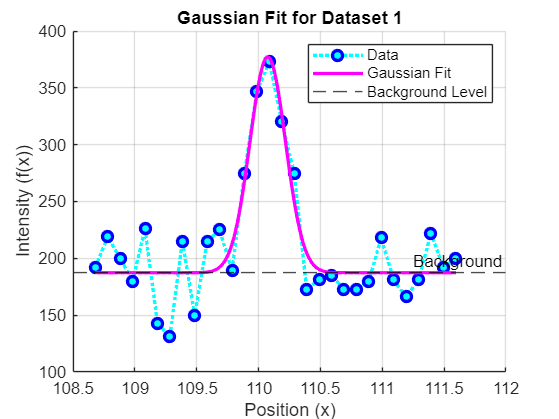

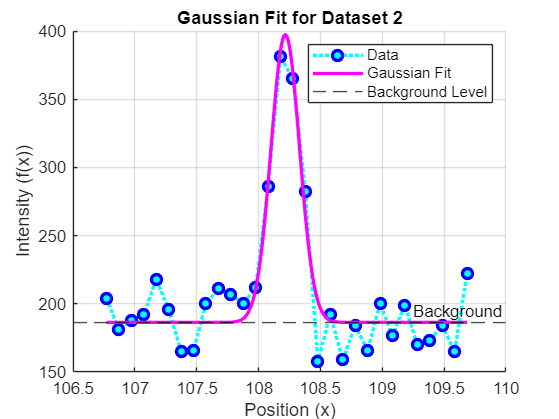

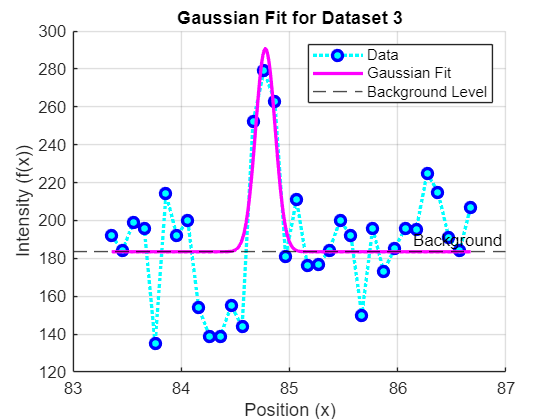

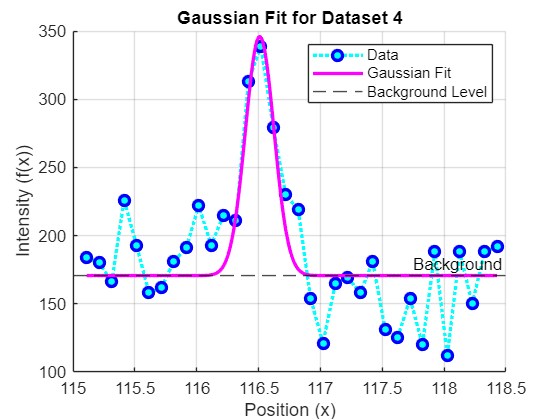

clc; clear all; close all;

% Add the Impsector Excel folder to the MATLAB path
addpath('C:\Users\allis\OneDrive - Yale University\Imspector\Excel');

% Import file
fileName = 'Imsp_60x_CF40_stack03_8f0__01.xlsx'; 
data = readtable(fileName); 
data = data(2:end, :); % this skip headers which are Imspector file names

% Determine number of columns (excluding the first column if it’s just an index)
numCols = width(data);
numDatasets = (numCols) / 2; % Assuming each dataset has an (x,y) pair

% Store results
w0_values = ones(numDatasets, 1);  % Preallocate storage

% Loop through each dataset
for i = 1:numDatasets
    % Extract x and y values
    col_x = 2 * i - 1; % x-values in odd columns
    col_y = 2 * i;     % y-values in even columns

    % Ensure there are no NaN values (for variable row lengths)
    validIdx = ~isnan(data{:, col_x}) & ~isnan(data{:, col_y});
    x = data{validIdx, col_x};
    y = data{validIdx, col_y};
    
    % Skip if dataset is empty
    if isempty(x) || isempty(y)
        continue;
    end

    % Find the index of the maximum y value
    [~, max_index] = max(y);
    x0 = x(max_index); % Initial peak location guess

    % Define the Gaussian function with background
    gaussian = @(params, x) params(1) * exp(-((x - params(2)).^2) / (2 * params(3)^2)) + params(4);

    % Define the error function (sum of squared residuals)
    error_function = @(params) sum((gaussian(params, x) - y).^2);

    % Initial parameter guesses [a0, x0, w0, B]
    initial_guess = [max(y), x0, 0.1, min(y)];  % w0 = 0.1 (initial)

    % Perform optimization
    options = optimset('MaxIter', 100, 'Display', 'off');
    optimized_params = fminsearch(error_function, initial_guess, options);

    % Extract optimized w0 value
    w0_values(i) = optimized_params(3); % Store optimized w0

    % Generate fitted curve
    x_fit = linspace(min(x), max(x), 300);
    y_fit = gaussian(optimized_params, x_fit);

    % Plot individual Gaussian fits (optional)
    figure;
    hold on;
    % Data
    plot(x, y, 'co:', 'MarkerFaceColor', 'c', 'MarkerEdgeColor', 'b', 'LineWidth', 2);
    % Gaussian Fit
    plot(x_fit, y_fit, 'm-', 'LineWidth', 2);
    yline(optimized_params(4), '--', 'Background', 'Color', 'k');
    xlabel('Position (x)');
    ylabel('Intensity (f(x))');
    title(['Gaussian Fit for Dataset ', num2str(i)]);
    legend('Data', 'Gaussian Fit', 'Background Level');
    grid on;
    hold off;
end


% Convert results to a table
w0_table = array2table(w0_values, 'VariableNames', {'Optimized_w0'});

% Display the table
disp('Optimized w0 values:');

Optimized w0 values:


disp(w0_table);

    Optimized_w0
    ____________

       0.14386  
       0.11535  
      0.090499  
       0.11566  



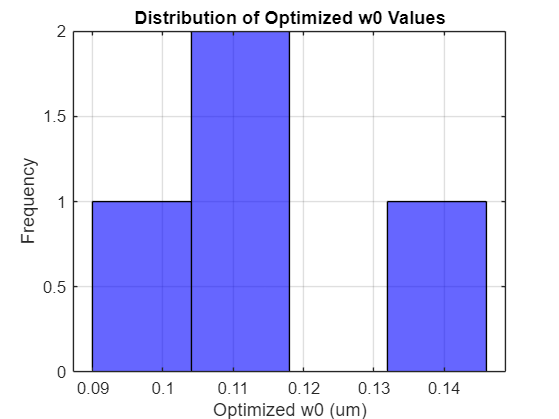


% Plot histogram of optimized w0 values
figure;
histogram(w0_values, numDatasets, 'FaceColor', 'b', 'EdgeColor', 'k');
xlabel('Optimized w0 (um)');
ylabel('Frequency');
title('Distribution of Optimized w0 Values');
grid on;